# Linear Control Design 2 - Fall 2019 - Exam Part I

## Introduction

The Part I of the Exam in Linear Control Design 2 (E19) consists of numerical exercises testing the acquisition of competences in the areas of analysis and design of control systems using modern control theory based on state space representation of system dynamics.

**The scoring of each problem is clearly stated.** 

It is the sole responsability of the student to guarantee that the solution delivered for evaluation can be run by the examiner without the need of contacting the student. All dependencies on files external to this Matlab Live Script must be checked and included in the final delivery. **If the examiner will not be able to execute the Matlab Live Script delivered as solution by the student, the Part I will be considered failed.** 

% Fill in your information
Exam = 'LCD2 E19'

Exam = 'LCD2 E19'

Student_Name = 'Student Name'

Student_Name = 'Student Name'

Student_Number = 'Student Number'

Student_Number = 'Student Number'

## Optimal control of an active suspension system

The suspension system is a key component of the vehicle directly affecting the passenger comfort and the ability of the vehicle itself to hold the road. In active suspension system an actuator is positioned between the sprung mass of the vehicle and the unsprung mass (wheel, tyre, brake, etc.) parallel to the suspension elements with the objective of pulling/pushing the vehicle body in order to suppress the vibrations due to road irregularities.

### Quarter-car suspension system

The system dynamics of a suspension system for a single wheel is descibed by

$m_s\ddot{z}_s = -b_s(\dot{z}_s-\dot{z}_u) - k_s(z_s-z_u) + f_a \\
m_u\ddot{z}_u = b_s(\dot{z}_s-\dot{z}_u) + k_s(z_s-z_u) - f_a + b_t(\dot{z}_r-\dot{z}_u) + k_t(z_r-z_u)$           (1)

where

- $m_s, \, b_s, \, k_s$ are the mass, damping and stiffness of the sprung element (quarter-car)

- $m_u, \, b_t, \, k_t$ are the mass, damping and stiffness of the unsprung element (wheel-tyre-brake)

- $z_s$ is the displacement of the sprung element

- $z_u$ is the displacement of the unsprung element

- $z_r$ is the displacement of the road

- $f_a$ is the force exerted by an hydraulic actuator placed between the sprung and unsprung elements

The applied force on the tyre from the road 

$f_d =  b_t\dot{z}_r + k_tz_r$                                                               (2)

is considered as an unknown disturbance in the sytem, which should be properly handled by the active suspension. Based on this, the system dynamics in Eq. (1) can be rewritten as

$m_s\ddot{z}_s = -b_s(\dot{z}_s-\dot{z}_u) - k_s(z_s-z_u) + f_a \\
m_u\ddot{z}_u = b_s(\dot{z}_s-\dot{z}_u) + k_s(z_s-z_u) - b_t\dot{z}_u - k_tz_u - f_a +f_d$     (3)

The following figure details the schematic of the system with all the relevant quantities.

 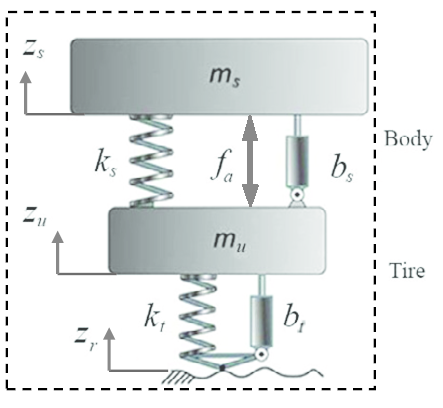

The linear model in Eq. (1) is implemented in the Simulink file QuarterCar_ActiveSusp_SimulinkYYYYC, where YYYYC refers to the Simulink version (2019b, 2019a, 2018b, 2018a, 2017b, 2017a, 2016b, 2016a). The numerical values for the model parameters are provided right below.

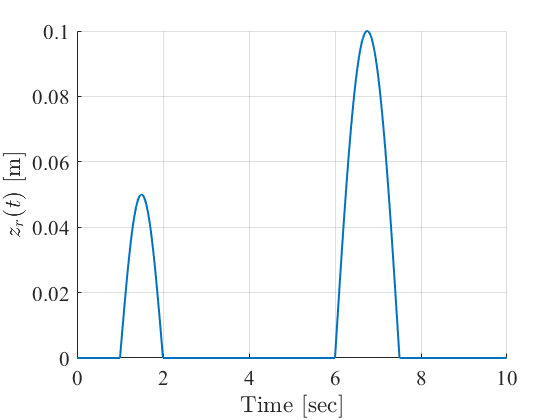

% Model paramters (RG)
% System parameters
m_s = 243; % sprung mass [kg]
m_u = 40; % unsprung mass [kg]
b_s = 370; % damping coefficient [N*s/m]
b_t = 414; % tyre damping coefficient [N*s/m]
k_s = 14761; % stiffness coefficient [N/m]
k_t = 124660; % tyre stiffness coefficient [N/m]

% Road profiles for open and closed-loop simulations (RG)
load road_profile.mat
time_det = time_det'; % column vector
time_stc = time_stc'; % column vector
z_r_det = z_r_det'; % column vector
z_r_stc = z_r_stc'; % column vector
% two road profiles are included:
% [t_det,z_r_det,z_r_dot_det] - deterministic road profile where t_det is the
% travelling time, z_r_det is the vertical road displacement and z_r_dot_det
% is the rate of change of the road profile.
% [t_stc,z_r_stc,z_r_dot_stc] - stochastic road profile where t_stc is the
% travelling time, z_r_stc is the vertical road displacement and z_r_dot_stc 
% is the rate of change of the road profile.
% Both profiles have been generated for a car traveling with a forward
% speed of 40 km/h

% Plot road profiles (RG)
% Deterministic road profile
figure, h1 = axes; set(h1,'FontName','times','FontSize',16)
hold on, grid on
plot(time_det,z_r_det,'LineWidth',1.5)
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
ylabel('$z_r(t)$ [m]','FontName','times','FontSize',16,'Interpreter','latex')

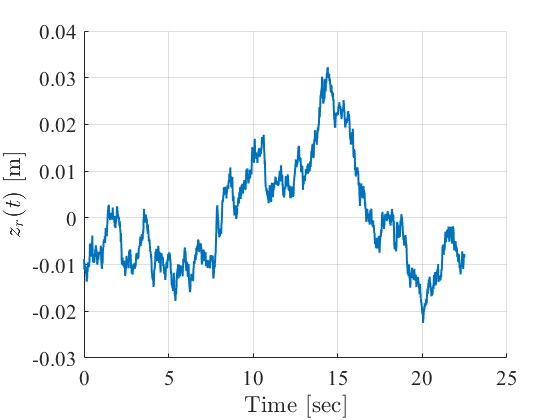

% Stochastic road profile
figure, h2 = axes; set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(time_stc,z_r_stc,'LineWidth',1.5)
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
ylabel('$z_r(t)$ [m]','FontName','times','FontSize',16,'Interpreter','latex')

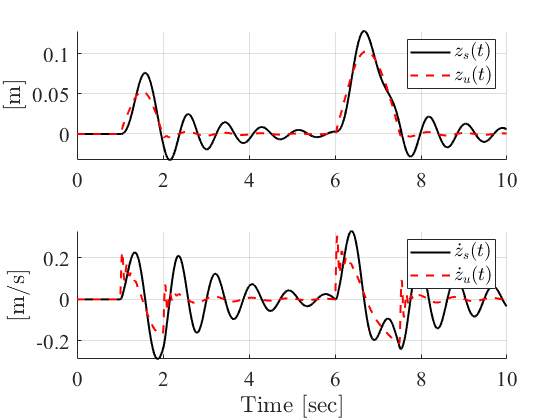

% Test the provided active suspension model on deterministic road profile (RG)
SIM_TIME = time_det(end); % simulation time (can be changed as needed)
STEP_SIZE = 0.01; % integration step size of Simulink (can be changed as needed)
% Change with the name of the model you are using
SIMULINK_FILENAME = 'QuarterCar_ActiveSusp_Simulink2019b';
f_a = zeros(length(time_det),1);
sim(SIMULINK_FILENAME,SIM_TIME,[],[time_det f_a z_r_det z_r_dot_det])

% Plot the temporal behaviour of the state variables
z_s = logsout.getElement('z_s').Values.Data;
z_s_dot = logsout.getElement('z_s_dot').Values.Data;
z_u = logsout.getElement('z_u').Values.Data;
z_u_dot = logsout.getElement('z_u_dot').Values.Data;

figure, h5 = subplot(2,1,1); set(h5,'FontName','times','FontSize',16)
hold on, grid on
plot(time_det,z_s,'k',time_det,z_u,'--r','LineWidth',1.5)
ylabel('[m]','FontName','times','FontSize',16,'Interpreter','latex')
leg1 = legend('$z_s(t)$','$z_u(t)$');
set(leg1,'FontName','times','FontSize',14,'Interpreter','latex')
h6 = subplot(2,1,2); set(h6,'FontName','times','FontSize',16)
hold on, grid on
plot(time_det,z_s_dot,'k',time_det,z_u_dot,'--r','LineWidth',1.5)
ylabel('[m/s]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
leg2 = legend('$\dot{z}_s(t)$','$\dot{z}_u(t)$');
set(leg2,'FontName','times','FontSize',14,'Interpreter','latex')

### Open-loop system analysis

**Problem 1 [2 points]** Based on the system dynamics described in Eq. (3), set up the linear state space model of the system.

% Your solution goes here





**Problem 2 [2 points]** Evaluate the internal and the external stability of system.

% Your solution goes here





**Problem 3 [2 points]** Assess the open-loop characteristics of the

- vertical acceleration $\ddot{z}_s$

- tire deflection $(z_u-z_r)$

- suspension deflection $(z_s-z_u)$

when the system is subject to the deterministic road profile $(z_r(t),\dot{z}_r(t))_\mathrm{det}$ in terms of largest deviation from the rest position, decay rate and settling time.

% Your solution goes here





### Control system design for vibration damping

The main control objectives are to improve the passenger comfort and vehicle handling in the presence of road profile variations by actively damping the introduced vibrations. The passenger comfort is evaluated in terms of vertical acceleration $\ddot{z}_s$ experienced by the sprung mass; whereas the vehicle handling is evaluated in terms of tire deflection $(z_u-z_r)$ and suspension deflection $(z_s-z_u)$.

Closed-loop system requirements

When subject to the deterministic road profile $(z_r(t),\dot{z}_r(t))_\mathrm{det}$ the closed-loop system is expected to fulfil the following requirements

- The peak of the vertical acceleration $\ddot{z}_s$ of the sprung mass is reduced by 20-40% in comparison to the peak displayed in open-loop (passive suspension)

- The vertical acceleration $\ddot{z}_s$ of the sprung mass settles to zero within 2-4 seconds since the time a road bump hits the tire

- The control effor $f_a$ is kept within $\pm1\,kN$

**Problem 4 [6 points]** Under the assumption that the state is fully accessible design a discrete time optimal controller that meets the aforementioned specifications using the linear quadratic regulator approach.

% Your solution goes here





**Problem 5 [2 points]** Implement the discrete time optimal controller in the given Simulink diagram and evalute the closed-loop system performance against the open-loop one, when the sytem is subject to the deterministic road profile $(z_r(t),\dot{z}_r(t))_\mathrm{det}$. Verify that the closed-loop requirements are fulfilled.

% Your solution goes here





### State estimation for output feedback control

In order to implement an output feedback controller for the active suspension, the state vector must be estimated based on available measurements. For the active suspension a common measurement easy to implement is the measurement of the acceleration of the sprung mass, i.e. $\ddot{z}_s$. Therefore in the last part of the exercise, we assume that the following measurement is available

$y_1 = \ddot{z}_s + v_1$                                                                   (4)

where $v_1$ is white noise with zero mean and noise intensity $I_{\ddot{z}_s} = 6.25\times10^{-4} \, m^2/s^4$. 

In the resolution of the following problems it is assumed that the system dynamics Eq. (3) is subject to the stochastic road profile $(z_r(t),\dot{z}_r(t))_\mathrm{stc}$.

**Problem 6 [6 points]** Under the assumption that the disturbance $f_d$ is unknown, design a discrete time Kalman filter able to reconstruct the state vector $\mathbf{x}= [z_s, \dot{z}_s,z_u,\dot{z}_u]^\mathrm{T}$.

% Your solution goes here





**Problem 7 [4 points]** Implement the discrete time Kalman filter in the Simulink diagram of the open-loop system and assess its estimation performance when the open-loop system is subject to the stochastic road profile $(z_r(t),\dot{z}_r(t))_\mathrm{stc}$

% Your solution goes here



